clc
clear
close all

T = 10;
tau = 1e-2;
x0 = 0;
alpha = 1.5;
beta = 0.6;
max_continuous_delta = 0.1;


### 对称 $\alpha$-stable Lévy 过程 $X\left(t\right)$

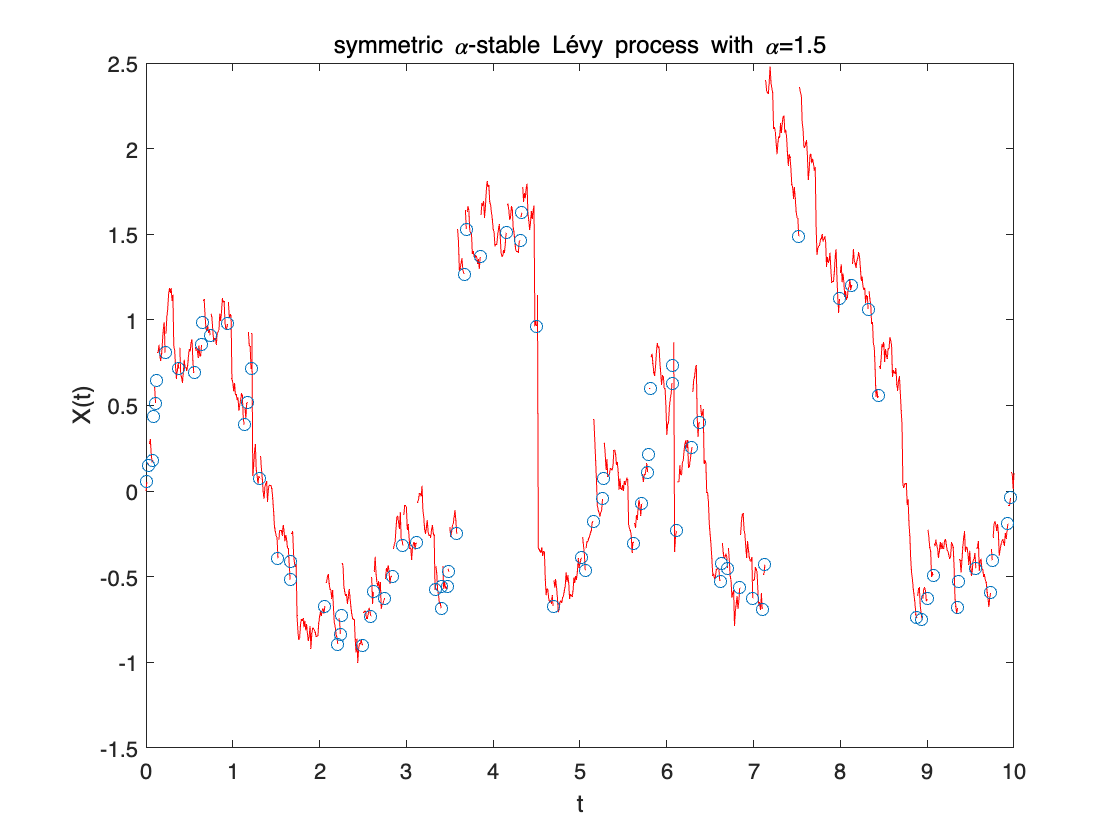

[t, x, delta_x] = Levy(alpha, T, x0, tau); 
figure()
[t_jump, x_jump] = plot_jump(t, x, 'r-', max_continuous_delta, delta_x);
hold on
plot(t_jump, x_jump, 'o')
xlabel("t")
ylabel("X(t)")
title("symmetric \alpha-stable Lévy process with \alpha="+num2str(alpha))

### $\alpha$-stable subordinator $S\left(t\right)$

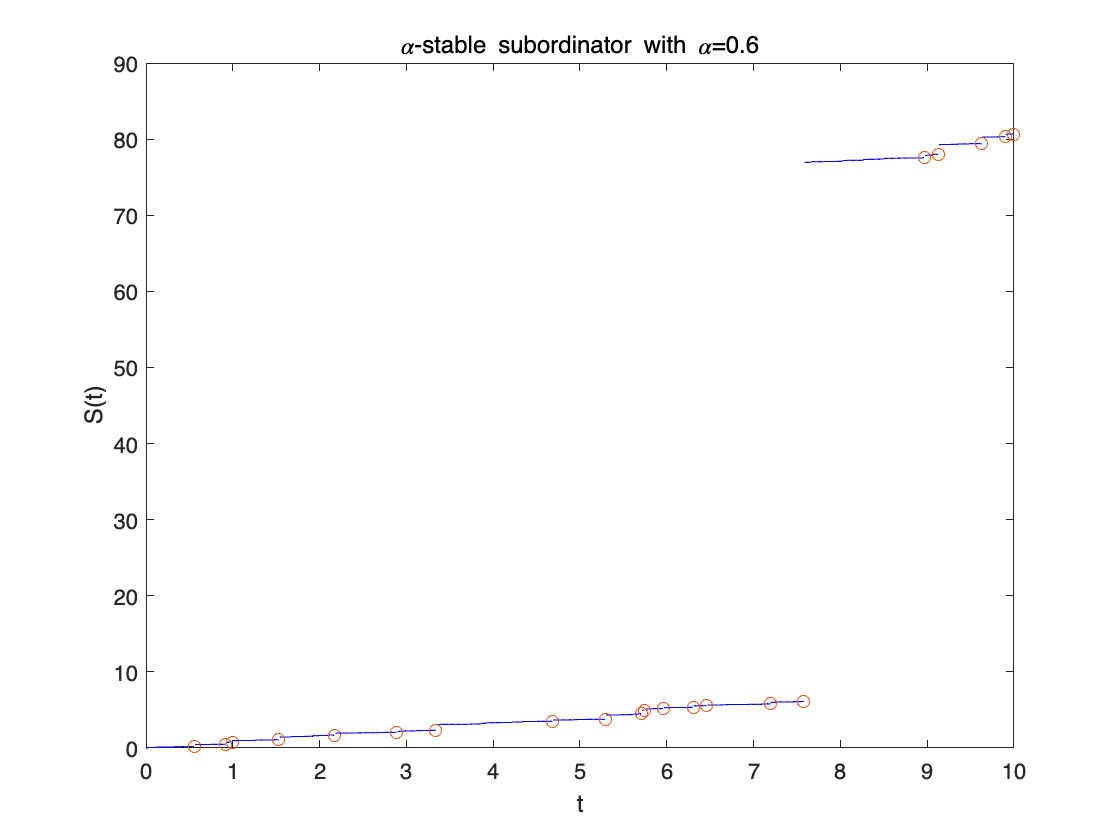

[t, S, delta_s] = subordinator(beta, T, tau);
figure()
[t_jump, x_jump] = plot_jump(t, S, 'b-', max_continuous_delta, delta_s);
hold on
plot(t_jump, x_jump, 'o')
xlabel("t")
ylabel("S(t)")
title("\alpha-stable subordinator with \alpha="+num2str(beta))

### Inverse $\alpha$-stable subordinator $E\left(t\right)$

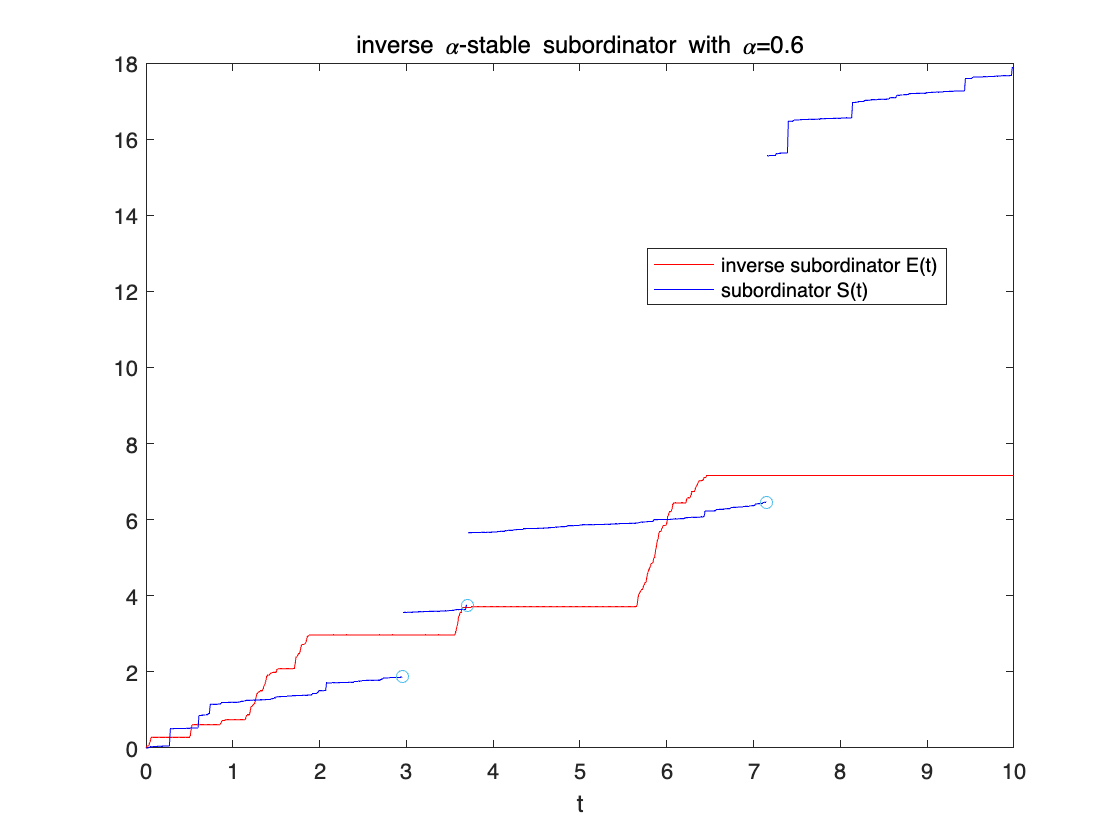

[t, invS, t_s, S] = inv_subordinator(beta, T, tau);
figure()
plot(t, invS, 'r-')
hold on
[t_jump, x_jump] = plot_jump(t_s, S);
hold on
plot(t_jump, x_jump, 'o')
xlabel('t')
title("inverse \alpha-stable subordinator with \alpha="+num2str(beta))
legend("inverse subordinator E(t)", "subordinator S(t)", 'Location','best')

### Subordinated Brownian motion $B\left(S\left(t\right)\right)$

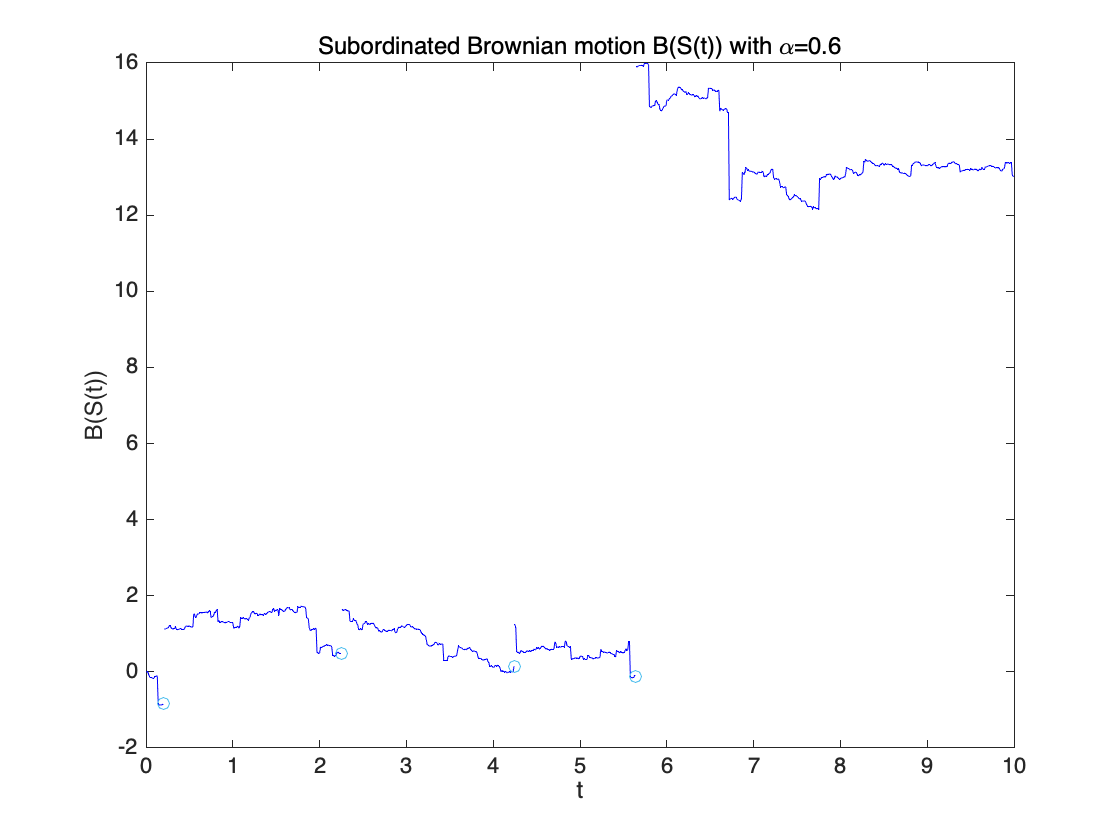

[t, x] = subm(beta, T, tau);
figure()
[t_jump, x_jump] = plot_jump(t, x);
hold on
plot(t_jump, x_jump, 'o')
xlabel('t')
ylabel('B(S(t))')
title("Subordinated Brownian motion B(S(t)) with \alpha="+num2str(beta))

### Subordinated Brownian motion $B\left(E\left(t\right)\right)$

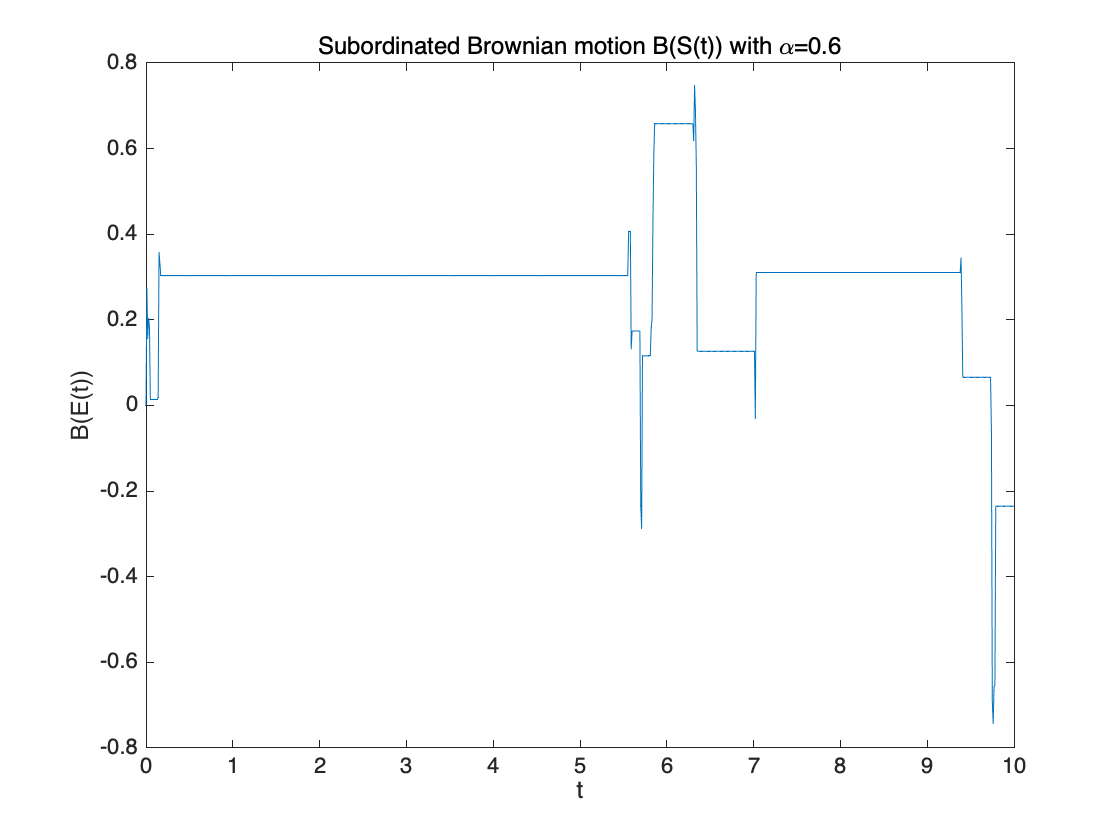

[t, x] = inv_subm(beta, T, tau);
figure()
plot(t, x)
xlabel('t')
ylabel('B(E(t))')
title("Subordinated Brownian motion B(S(t)) with \alpha="+num2str(beta))

### Killed time-changed Brownian motion ${B\left(S\left(t\right)\right)}_{\textrm{kill}}$

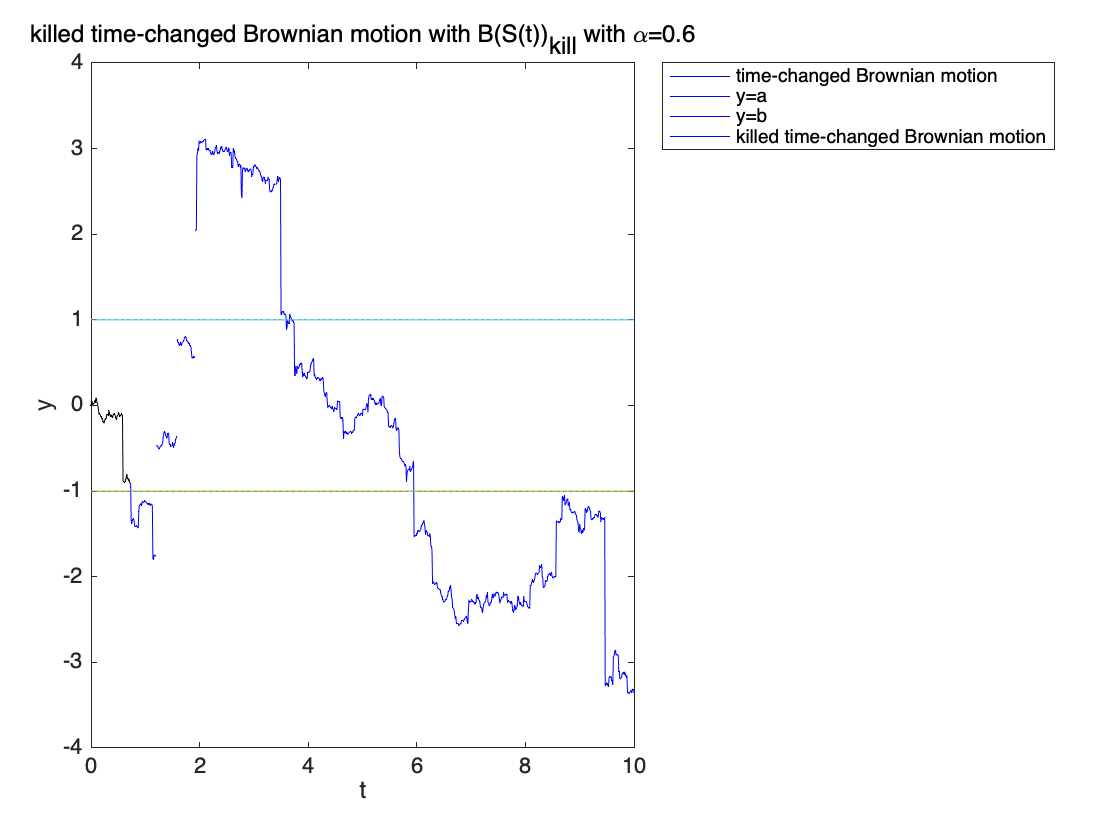

[t, x] = subm(beta, T, tau);
a = -1; b = 1;
n = length(t);
index  = (x <= b & x >= a);
temp = (1:n)';
temp = temp(index == 0);
if isempty(temp)
    index = n;
else
    index = temp(1)-1;
end
figure()
plot_jump(t, x)
hold on
plot(t, a*ones(n, 1))
hold on
plot(t, b*ones(n, 1))
hold on 
plot_jump(t(1:index), x(1:index),'k-')
xlabel('t')
ylabel('y')
legend('time-changed Brownian motion', 'y=a', 'y=b', ...
    'killed time-changed Brownian motion', 'Location','bestoutside')
title("killed time-changed Brownian motion with B(S(t))_{kill} with \alpha=" ...
    +num2str(beta))

### Time-changed killed Brownian motion $B_{\textrm{kill}} \left(S\left(t\right)\right)$

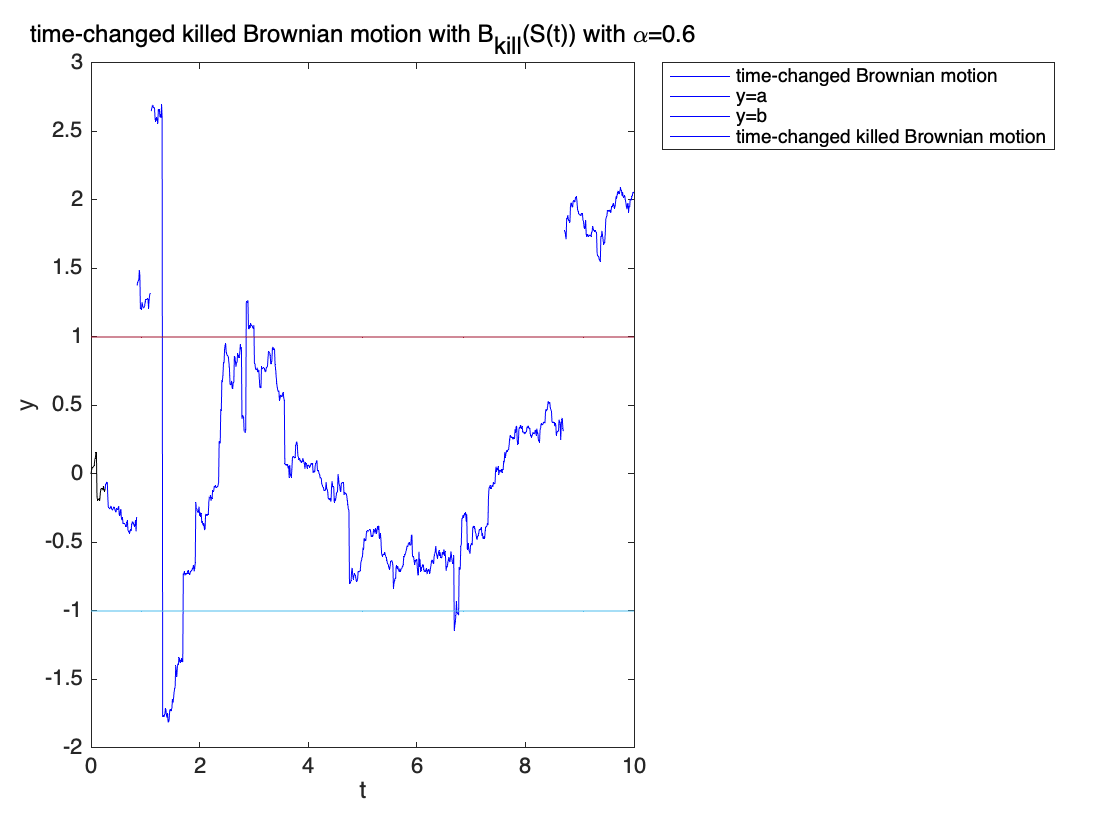

[t, S] = subordinator(beta, T, tau);
a = -1; b = 1;
n = length(S);
noise = normrnd(0, 1, n-1, 1);
x = [0; cumsum(sqrt(diff(S)) .* noise)];
B = [0; tau^(1/2) * cumsum(noise)];
index  = (B <= b & B >= a);
temp = (1:n)';
temp = temp(index == 0);
if isempty(temp)
    index = n;
else
    index = temp(1)-1;
end
figure()
plot_jump(t, x)
hold on
plot_jump(t(1:index), x(1:index), 'k-')
hold on
plot(t, a*ones(n, 1))
hold on
plot(t, b*ones(n, 1))
xlabel('t')
ylabel('y')
legend('time-changed Brownian motion', 'y=a', 'y=b', ...
    'time-changed killed Brownian motion', 'Location','bestoutside')
title("time-changed killed Brownian motion with B_{kill}(S(t)) with \alpha=" ...
    +num2str(beta))